Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 3**

% Defining some common functions to be used in this experiment

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

**Q1:**

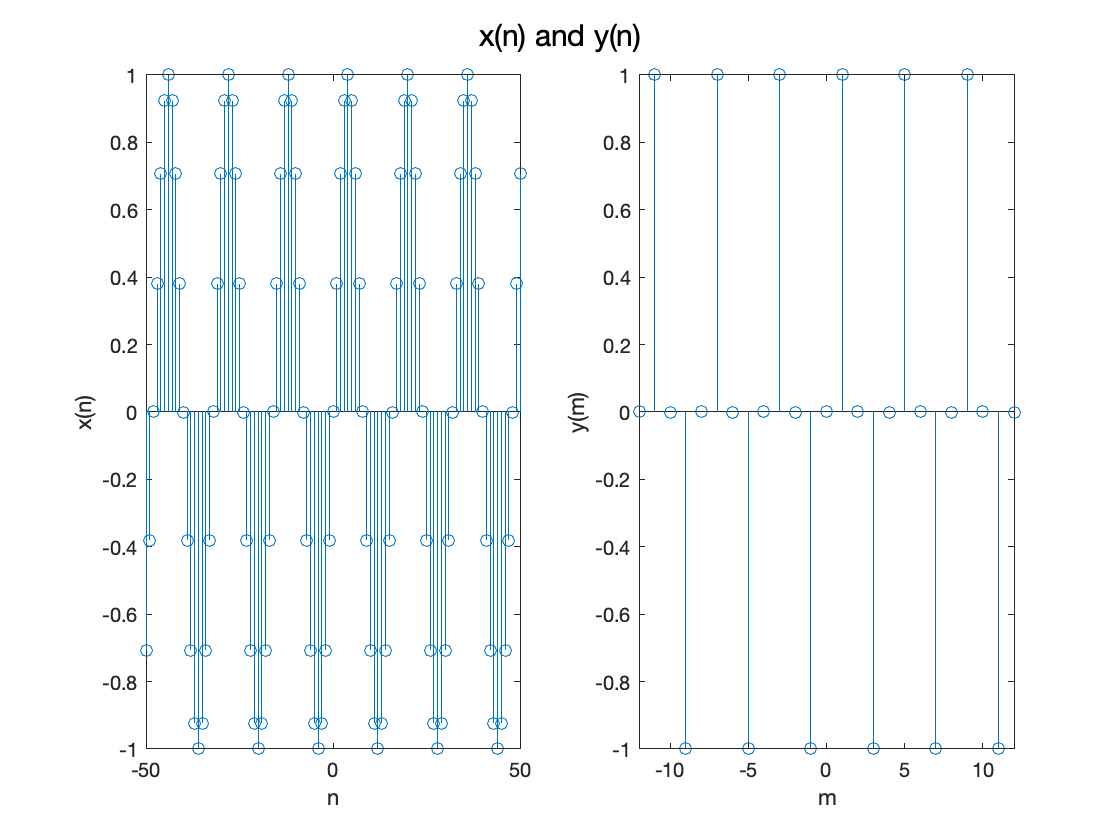

% a) The function dnsample() is defined at the end of this file.

% (b)
n = -50:50;
x = @(n) sin(0.125 * pi * n);
xn = x(n);
[y, m] = dnsample(xn, n, 4);

figure;
subplot(1, 2, 1);
stem(n, xn);
xlabel("n"); ylabel("x(n)");

subplot(1, 2, 2);
stem(m, y);
xlabel("m"); ylabel("y(m)");
sgtitle("x(n) and y(n)");

The downsampled signal $y(n)$ plotted above resembles a compressed version of the signal $x(n)$, from which a few entries have been chosen at regular intervals, and the remaining data points have been excluded.

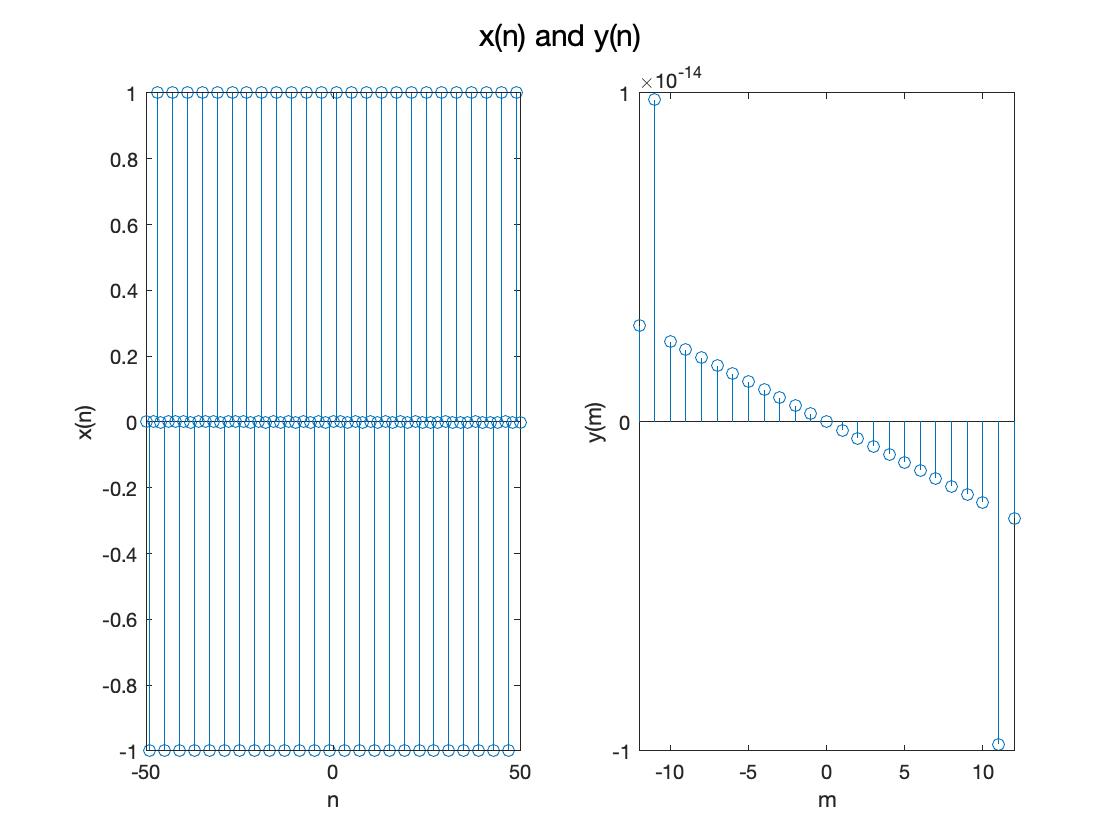

% (c)
x = @(n) sin(0.5 * pi * n);
xn = x(n);
[y, m] = dnsample(xn, n, 4);

figure;
subplot(1, 2, 1);
stem(n, xn);
xlabel("n"); ylabel("x(n)");

subplot(1, 2, 2);
stem(m, y);
xlabel("m"); ylabel("y(m)");
sgtitle("x(n) and y(n)");

Downsampling by N causes *aliasing* for any frequencies in the original signal above $\frac{\pi}{N}$. Additionally, in the context of DTFT, the time frequency axis is expanded by the factor $N$.

**Q2:**

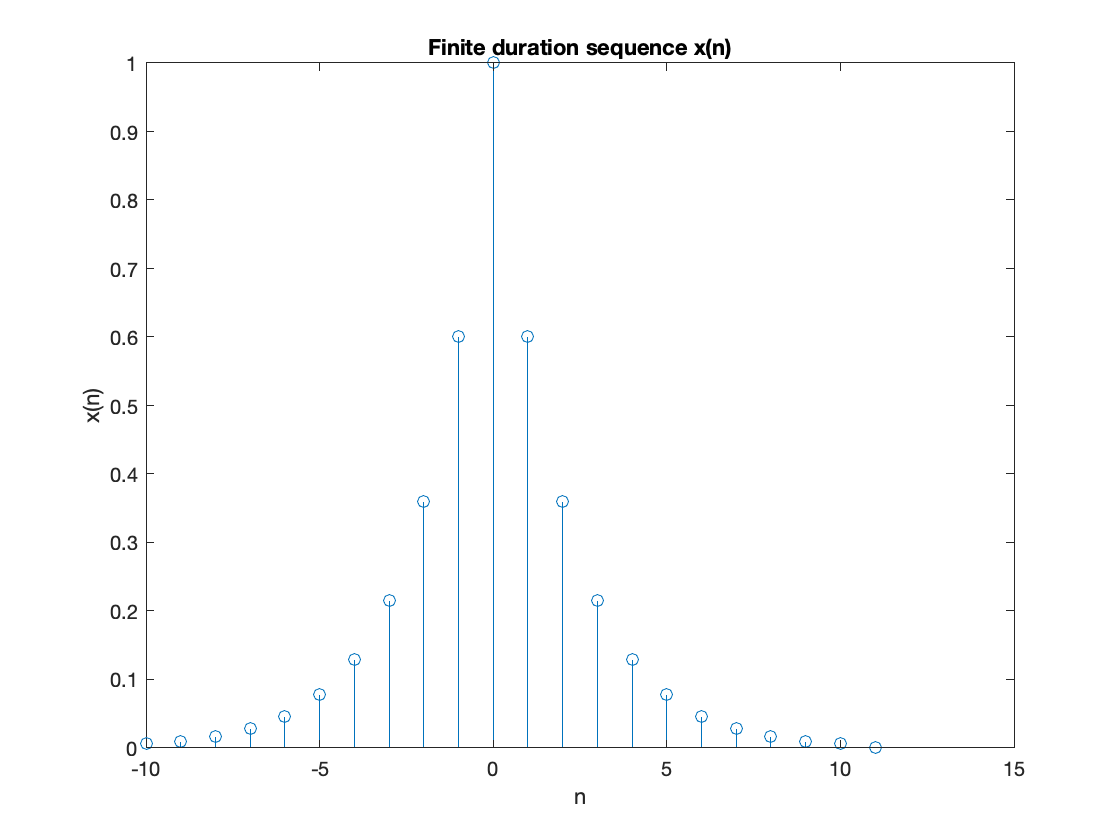

x = @(n) (0.6 .^ abs(n)) .* (u(n + 10) - u(n - 11));

% position vectors from -10 to 11
n = -10:11;

% finite duration sequence over n
xn = x(n);

% visualising the sequence x(n)
figure;
stem(n, xn);
xlabel("n"); ylabel("x(n)"); title("Finite duration sequence x(n)");

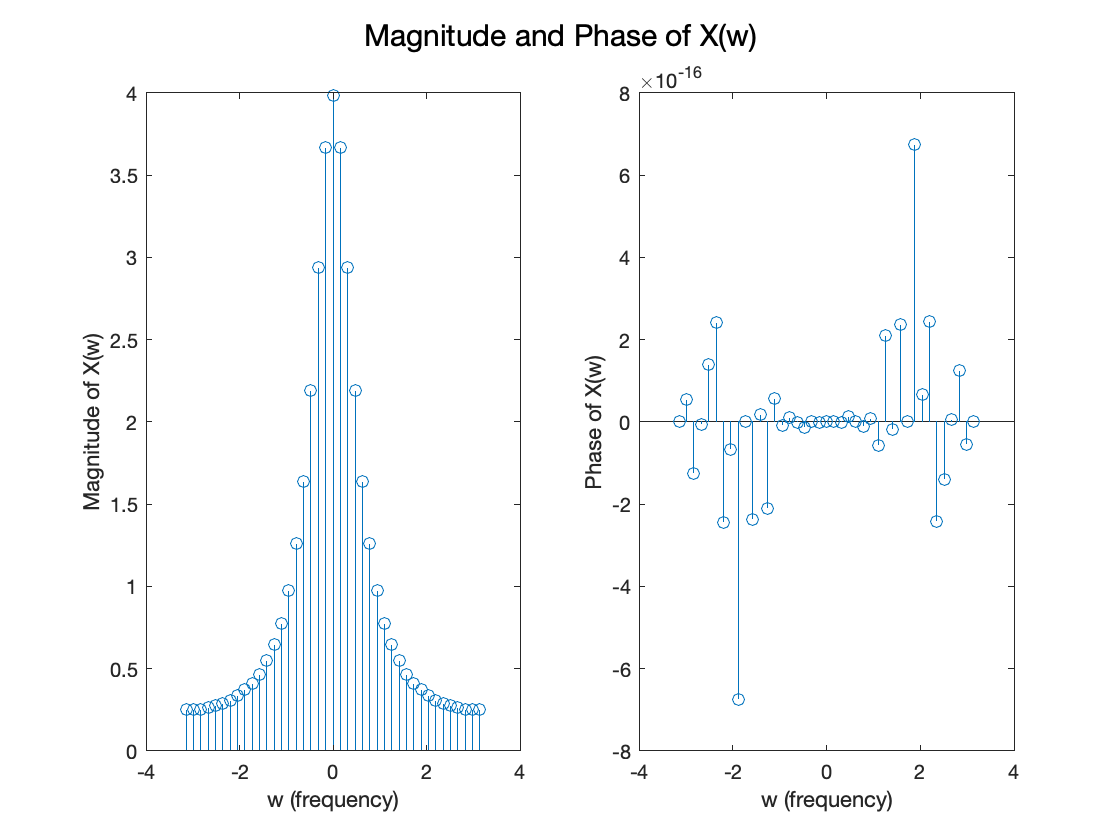

% 51 equispaced frequecy locations from -pi to +pi
w = -pi:(pi/20):pi;

X = dtft(xn, n, w);

% Plotting DTFT magnitude and phase
figure;
subplot(1, 2, 1);
stem(w, real(X));
xlabel("w (frequency)"); ylabel("Magnitude of X(w)");

subplot(1, 2, 2);
stem(w, angle(X));
xlabel("w (frequency)"); ylabel("Phase of X(w)");
sgtitle("Magnitude and Phase of X(w)");

It is evident from the phase plot that it is an odd function of $\omega$. This implies that the time domain equivalent of the signal does not have a complex part. 

**Q3:**

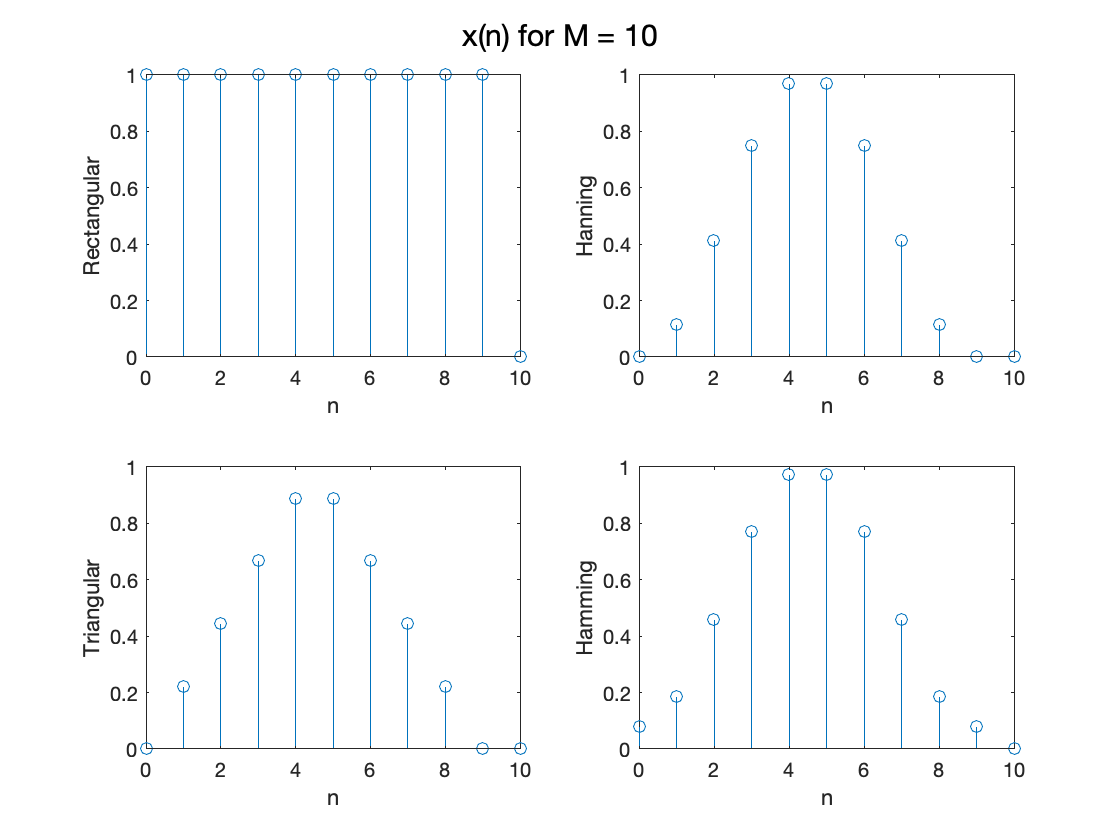

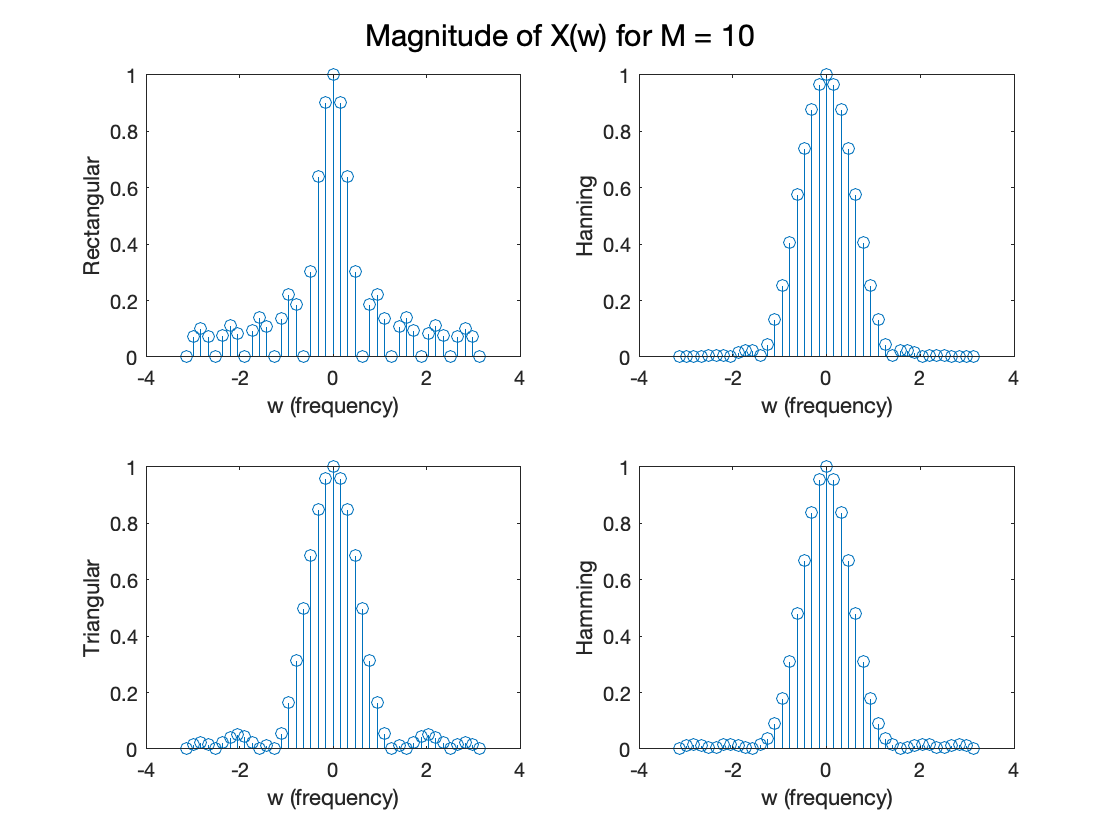

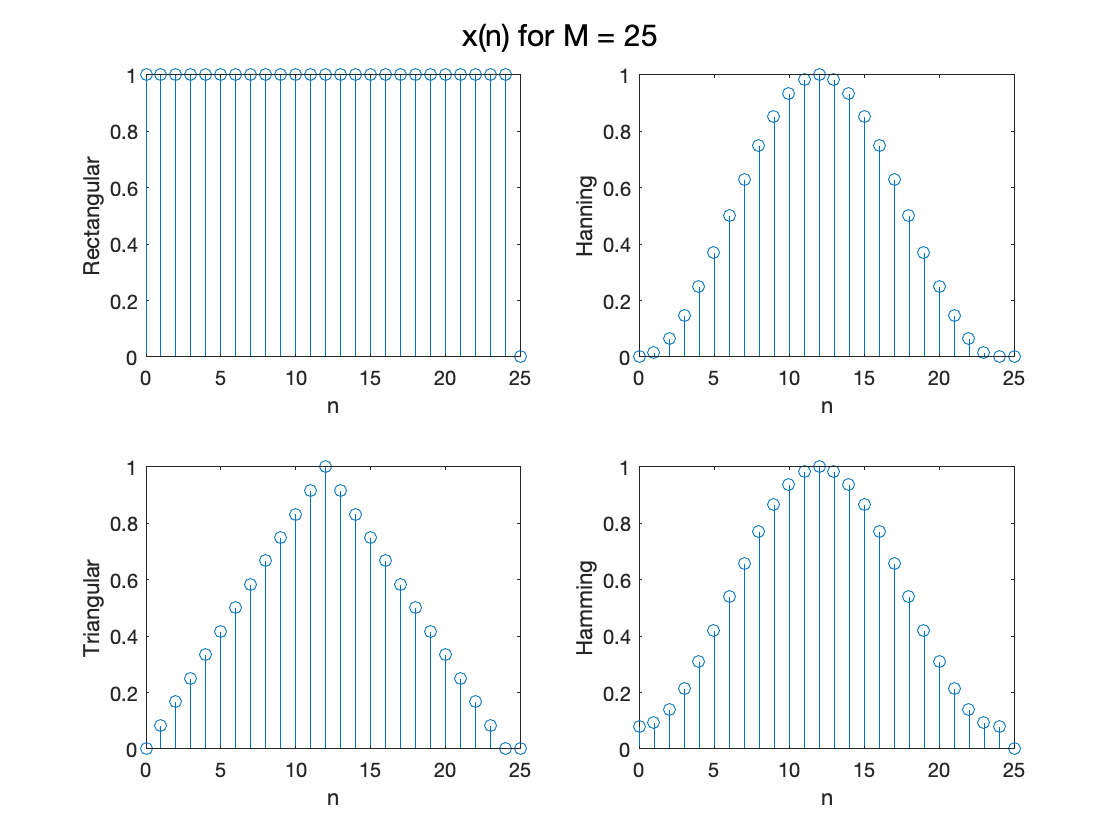

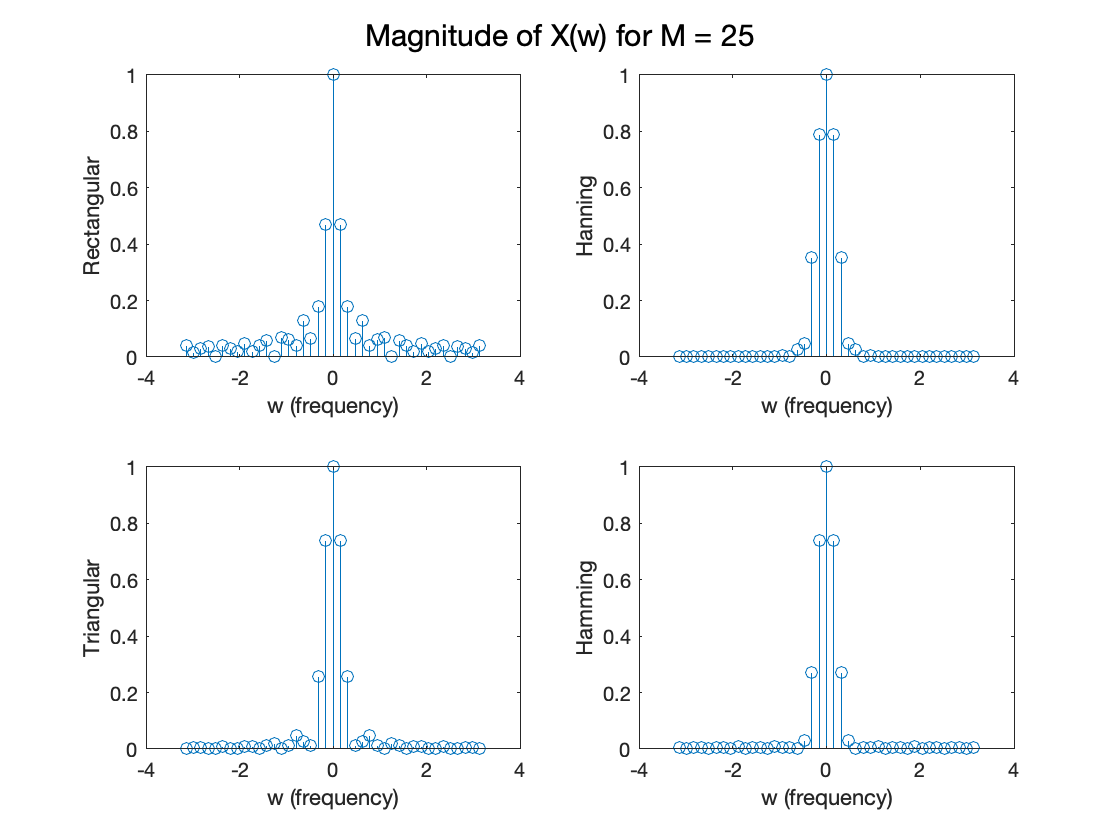

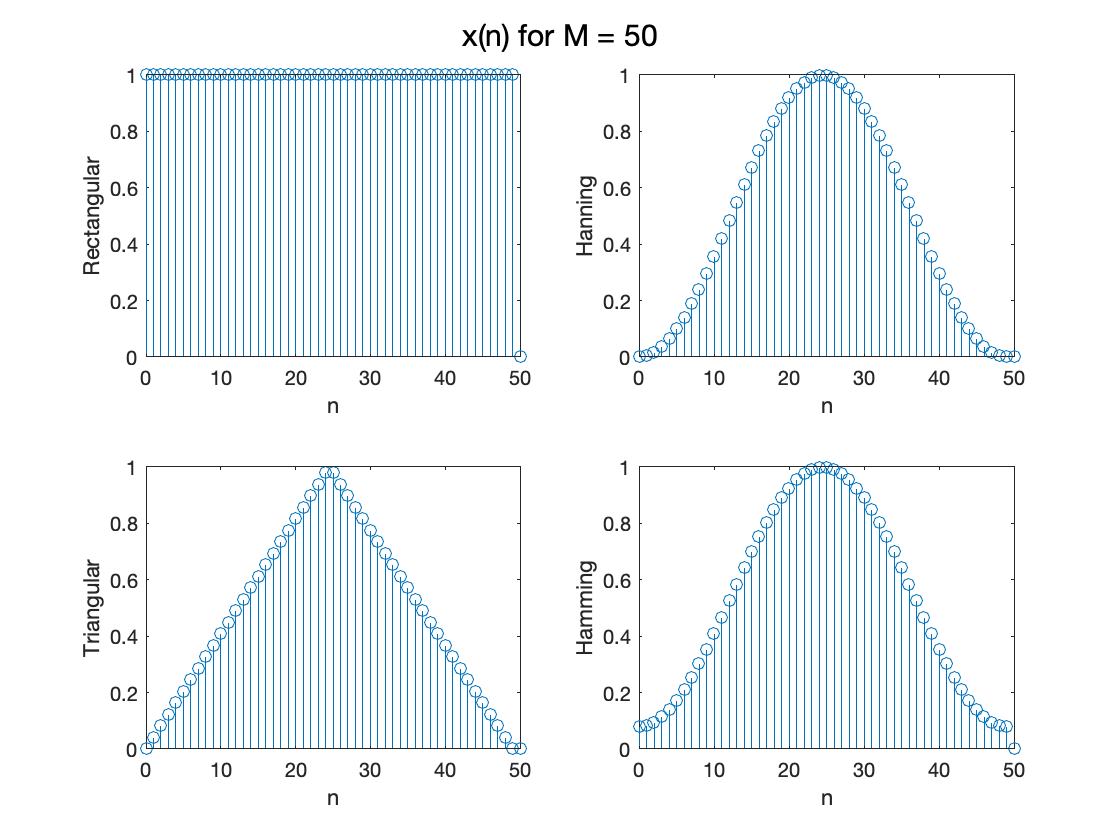

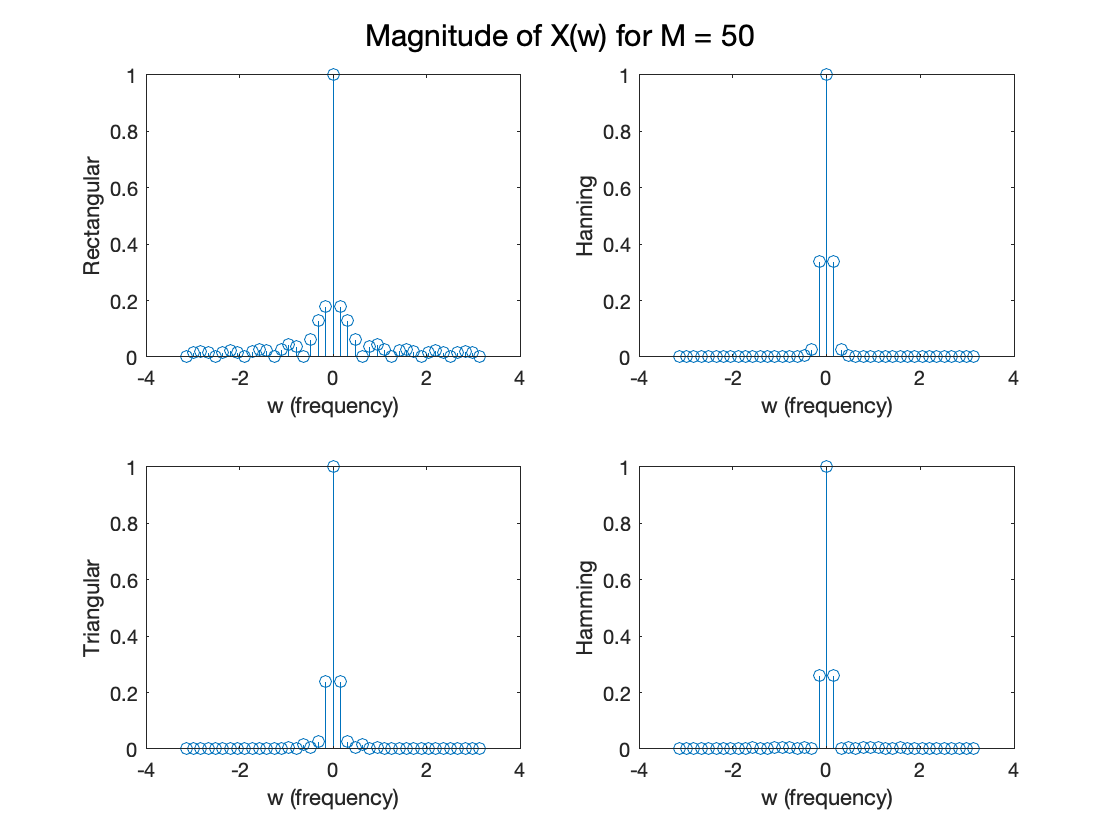

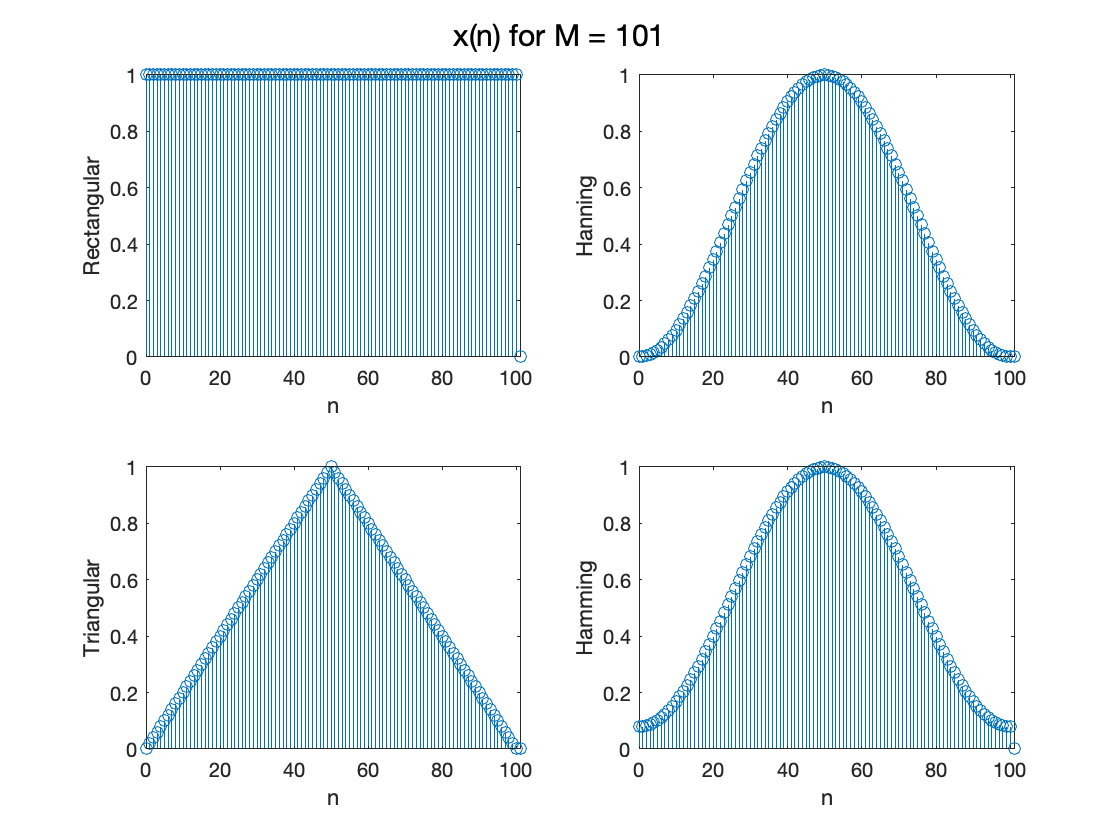

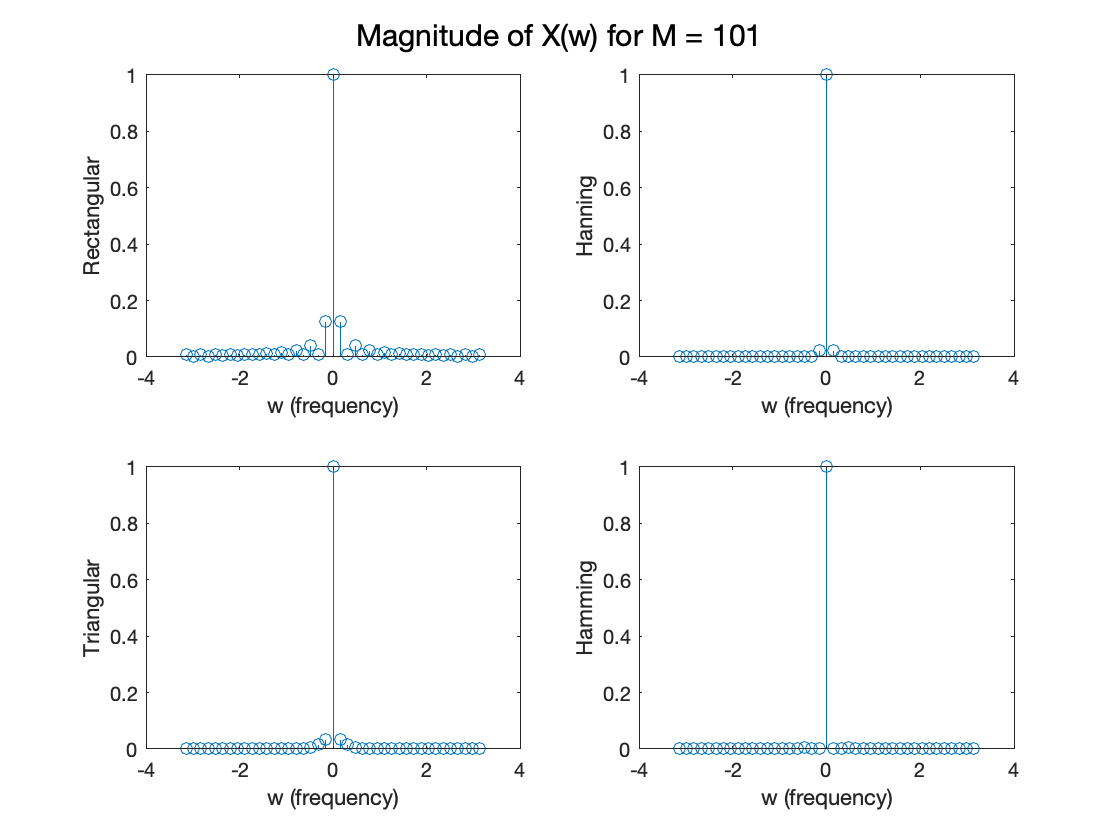

% Defining the windows
rectangular = @(M, n) u(n) - u(n - M);
hanning = @(M, n) 0.5 .* (1 - cos(2*pi*n/(M-1))) .* rectangular(M, n);
triangular = @(M, n) (1 - (abs(M - 1 - 2*n)/(M-1))) .* rectangular(M, n);
hamming = @(M, n) (0.54 - 0.46 .* cos(2*pi*n/(M-1))) .* rectangular(M, n);

M_values = [10, 25, 50, 101];
windows = {rectangular, hanning, triangular, hamming};
window_names = ["Rectangular", "Hanning", "Triangular", "Hamming"];

% 41 equispaced frequecy locations from -pi to +pi
w = -pi:(pi/20):pi;

for j = 1:length(M_values)
    M = M_values(j);
    n = 0:M;   
    
    signal_window = figure; 
    dtft_window = figure;
    for k = 1:length(windows)
        window = windows{k};
        signal = window(M, n);
        X = dtft(signal, n, w);
        
        % Normalising X(w)
        maxValue = max(abs(X));
        X = X ./ maxValue;
        
        % Plotting the time domain signal 
        figure(signal_window);
        subplot(2, 2, k);
        stem(n, signal);
        xlabel("n"); ylabel(window_names(k));
        
        % Plotting the magnitude of DTFT X(n)
        figure(dtft_window);
        subplot(2, 2, k);
        stem(w, abs(X));
        xlabel("w (frequency)"); ylabel(window_names(k));
    end
    figure(signal_window); sgtitle("x(n) for M = {" + M + "}")
    figure(dtft_window); sgtitle("Magnitude of X(w) for M = {" + M + "}");
end

It is evident from the above plots that with increasing values of $M$, the distribution of amplitudes of various frequencies becomes concentrated towards the origin. This means that the component having frequency zero becomes more prominent compared to other frequencies, at higher values of $M$.

function [y, m] = dnsample(x, n, M)
    len = length(x);
    y = []; m = [];
    for i = 1:len
        if mod(n(i), M) == 0
           y = [y x(i)];
           m = [m n(i)/M];
        end
    end
end

function X = dtft(x, n, w)
    X = x * exp(-1j .* (n' * w));
end